# MATLAB Tutorial 5. Root Locus Details

## Example 1.

>>>>> 개로전달함수의 극점 영점
poles:   1 ~ 2번 열

  -5.0000 + 0.0000i  -2.0000 - 1.0000i

  3번 열

  -2.0000 + 1.0000i

zeros:   -4.0000 - 2.0000i  -4.0000 + 2.0000i


>>>>> 근궤적의 점근선 구하기
발산하는 점근선의 개수: 1
점근선과 실수축이 만나는 점: -1.000000e+00
점근선의 각도(deg): 180.0 

>>>>> 극점 영점에서의 출발각 도착각 구하기
극점: -2.000+j1.000, 출발각: 101.310, 나머지각 합산: -78.690


극점: -2.000+j-1.000, 출발각: -101.310, 나머지각 합산: 78.690


영점: -4.000+j2.000, 도착각: 70.560, 나머지각 합산: -250.560


영점: -4.000+j-2.000, 도착각: -70.560, 나머지각 합산: 250.560


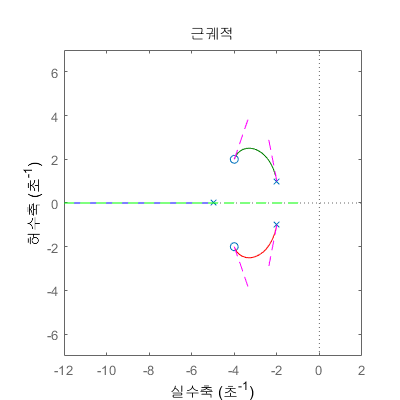

clc; clear
s = tf('s');
% GH = (s+8)/((s+2)*(s+4)*(s+6));
GH = (s^2+8*s+20)/(s^3+9*s^2+25*s+25);
root_locus(GH, 'asymptote', 'start_angle')

## Example 2.

>>>>> 개로전달함수의 극점 영점
poles:    -6.0000   -4.0000   -2.0000

zeros: 
>>>>> 근궤적의 점근선 구하기
발산하는 점근선의 개수: 3
점근선과 실수축이 만나는 점: -4
점근선의 각도(deg): 180.0 

-60.0 

60.0 

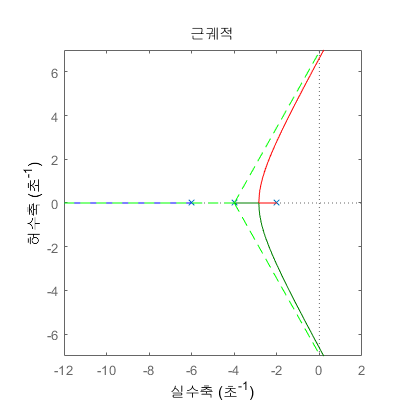

GH = 1/((s+2)*(s+4)*(s+6));
root_locus(GH, 'asymptote')

## Example 3.

>>>>> 개로전달함수의 극점 영점
poles:   1 ~ 2번 열

  -4.0000 - 3.0000i  -4.0000 + 3.0000i

  3번 열

  -2.0000 + 0.0000i

zeros: 
>>>>> 근궤적의 점근선 구하기
발산하는 점근선의 개수: 3
점근선과 실수축이 만나는 점: -3.333333e+00
점근선의 각도(deg): 180.0 

-60.0 

60.0 

>>>>> 극점 영점에서의 출발각 도착각 구하기
극점: -4.000+j3.000, 출발각: -33.690, 나머지각 합산: -213.690


극점: -4.000+j-3.000, 출발각: 33.690, 나머지각 합산: 213.690


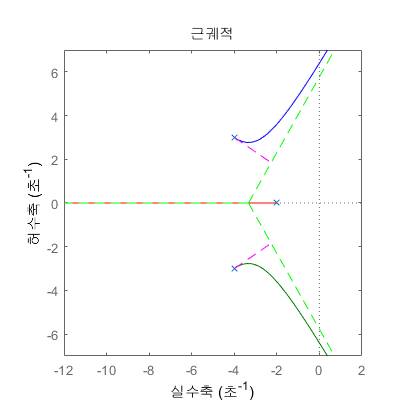

GH = 1/((s+2)*(s^2+8*s+25));
root_locus(GH, 'asymptote', 'start_angle')

## Example 4.

GH = (s^2+10*s+40)/((s^2+4*s+13)*(s^2+10*s+24));
root_locus(GH, 'start_angle', 'break_point')

>>>>> 개로전달함수의 극점 영점
poles:   1 ~ 2번 열

  -6.0000 + 0.0000i  -2.0000 - 3.0000i

  3 ~ 4번 열

  -2.0000 + 3.0000i  -4.0000 + 0.0000i

zeros:   -5.0000 - 3.8730i  -5.0000 + 3.8730i


>>>>> 극점 영점에서의 출발각 도착각 구하기
극점: -2.000+j3.000, 출발각: 47.015, 나머지각 합산: -132.985


극점: -2.000+j-3.000, 출발각: -47.015, 나머지각 합산: 132.985


영점: -5.000+j3.873, 도착각: -172.644, 나머지각 합산: -367.356


영점: -5.000+j-3.873, 도착각: 172.644, 나머지각 합산: 367.356


>>>>> 근궤적의 분기점 구하기
심볼릭 함수로 표현한 dK(w)/dw
              4       3       2
((2 w + 10) (w  + 14 w  + 77 w

                     2             2
   + 226 w + 312))/(w  + 10 w + 40)

        3       2
     4 w  + 42 w  + 154 w + 226
   - --------------------------
            2
           w  + 10 w + 40

분기점 후보: s = -5.9978 + j5.5098, K = 32.8396 + j72.1060 
분기점 후보: s = -5.9978 + j-5.5098, K = 32.8396 + j-72.1060 
근궤적의 분기점: s = -5.1527, K = 1.2313이다.


분기점 후보: s = -2.4259 + j1.6660, K = -2.3553 + j-1.6284 
분기점 후보: s = -2.4259 + j-1.6660, K = -2.3553 + j1.6284 


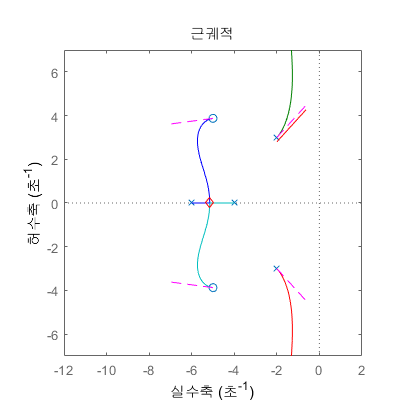

leng = 2;
angle = deg2rad(47);
hold on
plot([-2 -2+leng*cos(angle)], [3-0.2 3+leng*sin(angle)-0.2], 'r')
hold off

function root_locus(GH, varargin)
    [asymptote, break_point, start_angle] = parse_arg(varargin);
    
    rlocus(GH)
    hold on
    disp('>>>>> 개로전달함수의 극점 영점')
    fprintf('poles: ')
    disp(pole(GH)')
    fprintf('zeros: ')
    disp(zero(GH)')
    fprintf('\n')

    if asymptote
        draw_asymptote(GH, 'g--')
    end
    if start_angle
        draw_start_angle(GH, 2, 'm--')
    end
    if break_point
        draw_break_point(GH, 'rd')
    end
    
    hold off
    axis([-12 2 -7 7])
    set(gcf,'Position',[200 200 400 400])
end

function [asymptote, break_point, start_angle] = parse_arg(argcell)
    asymptote = 0;
    break_point = 0;
    start_angle = 0;
    for arg=argcell
        if strcmp(arg{1}, 'asymptote')
            asymptote = 1;
        elseif strcmp(arg{1}, 'break_point')
            break_point = 1;
        elseif strcmp(arg{1}, 'start_angle')
            start_angle = 1;
        end
    end
end

function draw_asymptote(GH, style)
    disp('>>>>> 근궤적의 점근선 구하기')
    poles = pole(GH);
    zeros = zero(GH);
    num_asym = size(poles,1) - size(zeros,1);
    fprintf('발산하는 점근선의 개수: %d\n', num_asym)
    asym_point = (sum(poles) - sum(zeros))/(num_asym);
    fprintf('점근선과 실수축이 만나는 점: %d\n', asym_point)
    fprintf('점근선의 각도(deg): ')
    for k=1:num_asym
        angle = (2*k+1)*pi / num_asym;
        asymptote_angle = rad2deg(atan2(sin(angle), cos(angle)));
        fprintf('%.1f ', asymptote_angle)
        % (asym_point, 0) -> (asym_point + 100*cos(angle), 100*sin(angle))
        plot([asym_point, asym_point + 100*cos(angle)], [0, 100*sin(angle)], style)
    end
    fprintf('\n\n')
end


function draw_break_point(GH, style)
    disp('>>>>> 근궤적의 분기점 구하기')
    [num, den] = tfdata(GH);
    num = num{1};
    den = den{1};

    syms w
    K_w = -poly2sym(den, w) / poly2sym(num, w);
    disp('심볼릭 함수로 표현한 dK(w)/dw')
    dK_w = diff(K_w);
    pretty(dK_w)
    % 근궤적의 교차점 후보 구하기 = dK_w의 분자가 0이 되는 해 구하기
    [num, den] = numden(dK_w);  % 분자의 추출
    num = sym2poly(num);        % 분자의 계수 추출
    breakpts = roots(num);      % 분자=0 의 해 계산
    for i=1:size(breakpts, 1)
        % 분기점으로부터 다시 K(s_i) 계산하기
        K_wi = double(subs(K_w, w, breakpts(i)));
        % 분기점에서 K는 양의 실수여야 한다.
        if (K_wi > 0) && (imag(K_wi) == 0)
            fprintf('근궤적의 분기점: s = %.4f, K = %.4f이다.\n', breakpts(i), K_wi)
            plot(breakpts(i), 0, style)
        else
            fprintf('분기점 후보: s = %.4f + j%.4f, K = %.4f + j%.4f \n', ...
                real(breakpts(i)), imag(breakpts(i)), real(K_wi), imag(K_wi))
        end
    end
end


function draw_start_angle(GH, linelen, style)
    disp('>>>>> 극점 영점에서의 출발각 도착각 구하기')
    poles = pole(GH);
    zeros = zero(GH);
    % 출발각
    not_on_real_axis = abs(imag(poles)) > 0;
    for i=1:length(poles)
        % 실수가 아닌 복소수일 때만 출발각 계산
        if not_on_real_axis(i) == 0
            continue            
        end
        angle_sum = 0;
        curpole = poles(i);
        % 다른 극점과의 각도 합산 빼기
        for k=1:length(poles)
            if i ~= k
                pole_ang = atan2(imag(curpole - poles(k)), real(curpole - poles(k)));
                angle_sum = angle_sum - pole_ang;
            end
        end
        % 다른 영점과의 각도 합산 더하기
        for k=1:length(zeros)
            zero_ang = atan2(imag(curpole - zeros(k)), real(curpole - zeros(k)));
            angle_sum = angle_sum + zero_ang;
        end
        % angle_sum - depart_ang = pi
        depart_ang = angle_sum - pi;
        depart_ang = atan2(sin(depart_ang), cos(depart_ang));
        fprintf('극점: %.3f+j%.3f, 출발각: %.3f, 나머지각 합산: %.3f\n', ...
                real(curpole), imag(curpole), rad2deg(depart_ang), rad2deg(angle_sum))
        
        cur_x = real(curpole);
        cur_y = imag(curpole);
        plot([cur_x, cur_x+linelen*cos(depart_ang)], [cur_y, cur_y+linelen*sin(depart_ang)], style)
    end
    
    % 도착각
    not_on_real_axis = abs(imag(zeros)) > 0;
    for i=1:length(zeros)
        % 실수가 아닌 복소수일 때만 도착각 계산
        if not_on_real_axis(i) == 0
            continue            
        end
        angle_sum = 0;
        curzero = zeros(i);
        % 다른 극점과의 각도 합산 빼기
        for k=1:length(poles)
            pole_ang = atan2(imag(curzero - poles(k)), real(curzero - poles(k)));
            angle_sum = angle_sum - pole_ang;
        end
        % 다른 영점과의 각도 합산 더하기
        for k=1:length(zeros)
            if i ~= k
                zero_ang = atan2(imag(curzero - zeros(k)), real(curzero - zeros(k)));
                angle_sum = angle_sum + zero_ang;
            end
        end
        % angle_sum + arrival_ang = pi
        arrival_ang = pi - angle_sum;
        arrival_ang = atan2(sin(arrival_ang), cos(arrival_ang));
        fprintf('영점: %.3f+j%.3f, 도착각: %.3f, 나머지각 합산: %.3f\n', ...
                real(curzero), imag(curzero), rad2deg(arrival_ang), rad2deg(angle_sum))
        
        cur_x = real(curzero);
        cur_y = imag(curzero);
        plot([cur_x, cur_x+linelen*cos(arrival_ang)], [cur_y, cur_y+linelen*sin(arrival_ang)], style)
    end
    fprintf('\n\n')
end